%p = '/asap3/petra3/gpfs/p07/2022/data/11012618/processed/etna_001_et16tard_a/reco/float_rawBin2';
p='/asap3/petra3/gpfs/p07/2022/data/11012618/processed/etna_068_cse100222g_f/reco/float_rawBin2';
vol = read_images_to_stack(p,1,'*.tif',[],1,0);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 16).

Parpool opened on local using 16 of 20 workers in 30.3 s (0.50 min)

n0 = 1;
n1 = size(vol,3);
ndefault = round((n1-n0)/2);
dn = 1;

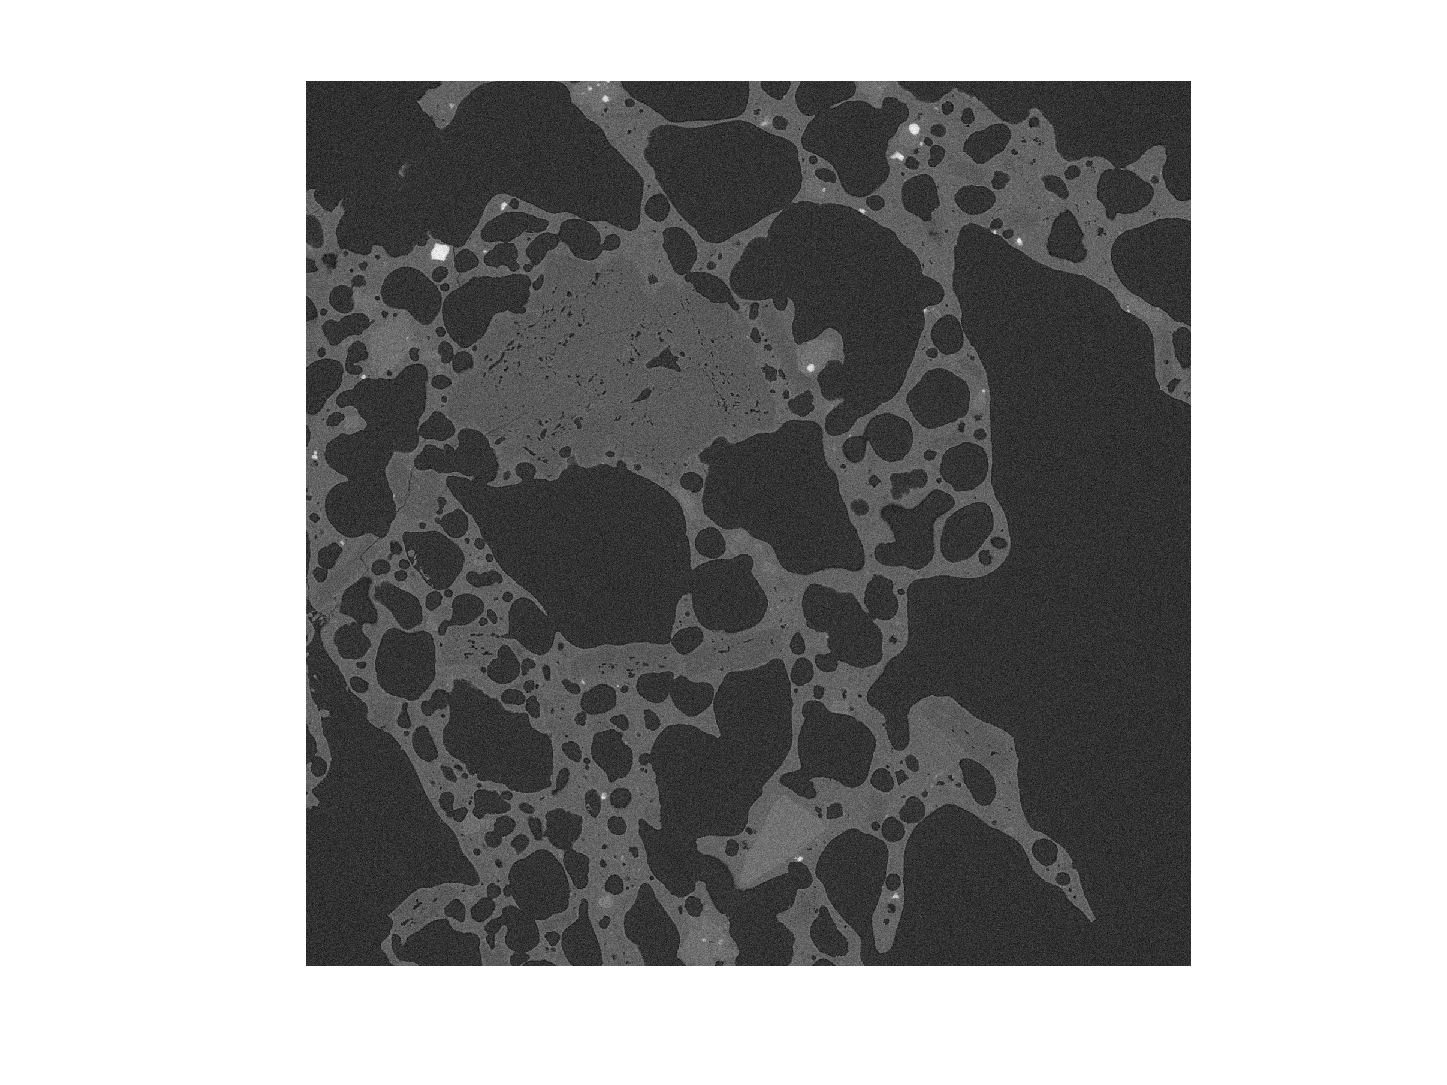

x = round( [0.2 0.8] * (size(vol,1) - 1) + 1);
y = round( [0.2 0.8] * (size(vol,2) - 1) + 1);
xr = x(1):x(2);
yr = y(1):y(2);
if ~exist('h', 'var') || ~isvalid(h)
    im = vol(xr,yr,round(size(vol,3)/2));
    imi = uint8(2^8 * normat( im ));
    h = imagesc('CData', imi);
    
end
hold on
colormap(gray)
axis image tight
xticklabels('')
yticklabels('')
z =494;
%im = vol(:,:,z);
%im = normat(im);
%dr = 10;
%dr = [dr, 100-dr] / 100;
%imsc(im)
%img = gpuArray(im);
hold on
%h = imagesc('CData', im);
%h.Parent.Position = [1 1 100 100];
im = vol(xr,yr,z);
imi = uint8(2^8 * normat(im));
%imshow(im,[])
%h.CData = im ;
h.Parent.Parent.Position =  [1300        1544         4*560         4*420];
imagesc('CData', imi)

%set(h.Parent,'Units','normalized','Position',[0 0 1 1]); 
drawnow
%refreshdata

x = round( [0.2 0.8] * (size(vol,1) - 1) + 1);
y = round( [0.2 0.8] * (size(vol,2) - 1) + 1);
xr = x(1):x(2);
yr = y(1):y(2);
% if ~exist('h', 'var') || ~isvalid(h)
%     im = vol(xr,yr,round(size(vol,3)/2));
%     imi = uint8(2^8 * normat( im ));
%     h = imagesc('CData', imi);
%     
% end
h.Parent.Parent.Renderer = 'opengl';
hold on
colormap(gray)
axis image tight
xticklabels('')
yticklabels('')
z =262;
%im = vol(:,:,z);
%im = normat(im);
%dr = 10;
%dr = [dr, 100-dr] / 100;
%imsc(im)
%img = gpuArray(im);
hold on
%h = imagesc('CData', im);
%h.Parent.Position = [1 1 100 100];
im = vol(xr,yr,z);
imi = uint8(2^8 * normat(im));
%imshow(imi,[], 'InitialMagnification', 200)
h.CData = imi ;
%imagesc('CData', imi)
%set(h.Parent,'Units','normalized','Position',[0 0 1 1]); 
drawnow
%refreshdata